# qRK Test **edits**

In this notebook, we're testing an implementation of tensor quantile randomized Kaczmarz.

addpath('tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent tensor linear system.

l = 5;
p = 7;
n = 10;
m = 12;
num_corrupt = 1; % number of corruptions 
size_corrupt= 100; % size of corruptions 

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);


Now, let's test the implementation of qRK.

%run some iterations of qRK
num_its = 1000;

%Try adding noise!
dims = prod(size(B));
ix_lin = randsample(dims,num_corrupt);



[ix_sub1, ix_sub2, ix_sub3] = ind2sub(size(B),ix_lin);
for i=1:num_corrupt
    % original line - corrupt 1 entry 
    B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) = B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) + size_corrupt;
end 



qv = 0.8 %quantile value

qv = 0.8000

[~,its] = qRK(A,B,randn(l,p,n),num_its); %quantile RK

Iteration: 9 -- Skipping slice 4, q = 0.91667
Iteration: 14 -- Skipping slice 9, q = 0.83333
Iteration: 25 -- Skipping slice 4, q = 0.91667
Iteration: 28 -- Skipping slice 2, q = 0.83333
Iteration: 31 -- Skipping slice 4, q = 0.91667
Iteration: 33 -- Skipping slice 2, q = 0.83333
Iteration: 35 -- Skipping slice 4, q = 0.91667
Iteration: 49 -- Skipping slice 4, q = 0.91667
Iteration: 53 -- Skipping slice 11, q = 0.83333
Iteration: 54 -- Skipping slice 11, q = 0.83333
Iteration: 63 -- Skipping slice 4, q = 0.91667
Iteration: 71 -- Skipping slice 4, q = 0.91667
Iteration: 75 -- Skipping slice 11, q = 0.83333
Iteration: 89 -- Skipping slice 4, q = 0.91667
Iteration: 95 -- Skipping slice 11, q = 0.83333
Iteration: 102 -- Skipping slice 11, q = 0.83333
Iteration: 103 -- Skipping slice 4, q = 0.91667
Iteration: 114 -- Skipping slice 4, q = 0.91667
Iteration: 127 -- Skipping slice 4, q = 0.91667
Iteration: 131 -- Skipping slice 2, q = 0.83333
Iteration: 136 -- Skipping slice 11, q = 0.83333
It

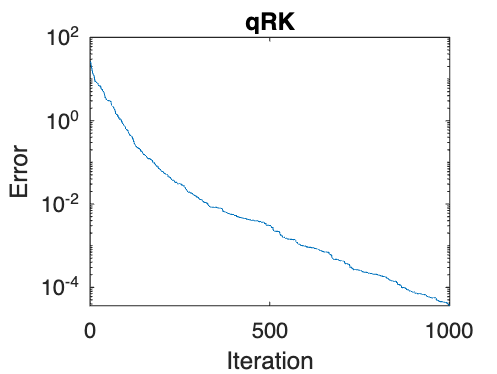


%record errors
errs = [];
for j = 1:num_its+1
    est = its{j} - X_true;
    errs = [errs,norm(est(:))];  
end


%plot errors vs iterations
semilogy(errs)
title('qRK')
xlabel ('Iteration')
ylabel('Error') 